clear

S = load('CCT_Duv_MaxMelDER.mat')

S = struct with fields:
    temp: [12×3 double]


maxData = S.temp;
S = load('CCT_Duv_MinMelDER.mat')

S = struct with fields:
    temp: [12×3 double]


minData = S.temp;
%%
fig = figure

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


sp1=subplot(2,2,1)

sp1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.58384 0.33466 0.34116]
            Units: 'normalized'

  Show all properties


title('Max And Min')
hold on
scatter(maxData(:,1),minData(:,2),'r','filled')
hold on
scatter(maxData(:,1),maxData(:,2),'g','filled')
xlabel('CCT')
ylabel('Melanopic DER')
grid on
%
% figure
sp2=subplot(2,2,2)

sp2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.57034 0.58384 0.33466 0.34116]
            Units: 'normalized'

  Show all properties



title('Abs Diff')
hold on
scatter(maxData(:,1), maxData(:,2)-minData(:,2),'filled')
xlabel('CCT')
ylabel('Max melDER - Min melDER')
%
grid on

% figure
sp3=subplot(2,2,3)

sp3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.33466 0.34116]
            Units: 'normalized'

  Show all properties



title('Michelson Contrast')
hold on
scatter(maxData(:,1), [maxData(:,2)-minData(:,2)]./[maxData(:,2)+minData(:,2)],'filled')
xlabel('CCT')
ylabel('Michelson Contrast, [max - min]/[max + min]')

grid on

% figure
sp4=subplot(2,2,4)

sp4 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.57034 0.11 0.33466 0.34116]
            Units: 'normalized'

  Show all properties


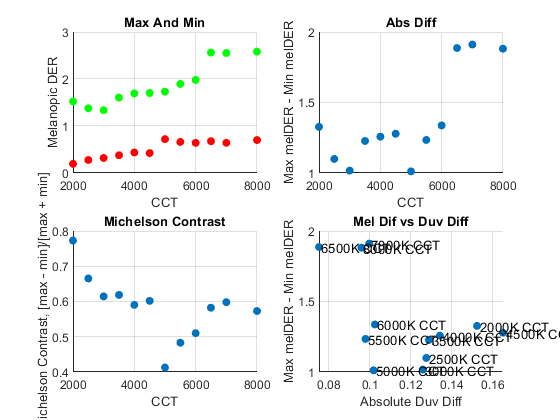


title('Mel Dif vs Duv Diff')
hold on
scatter(abs(maxData(:,3)-minData(:,3)), maxData(:,2)  -minData(:,2),'filled' )
text(abs(maxData(:,3)-minData(:,3))*1.01, maxData(:,2)-minData(:,2) , string(maxData(:,1))+"K CCT" )
xlabel('Absolute Duv Diff')
ylabel('Max melDER - Min melDER')
grid on

Ok so I now went through and said that the min must be constrained only to the LMS values of the max. Its cct could be whatever

minDataLMSRef.cctOut = [2134.8	2645.8	3202.6	3768.1	3440	4171.2	4951	8318	6594.5	9552.3 11632	10479
];
minDataLMSRef.cctRef = [2000 2500 3000 3500 4000 4500 5000 5500 6000 6500 7000 8000];
minDataLMSRef.melDER = [1.33123	1.1942	1.19397	1.32645	1.52599	1.45812	1.45834	1.5839	1.7086	2.4426 2.3403	2.4305
];
minDataLMSRef.duv   = [-0.1396	-0.11075	-0.099638	-0.085564	-0.088513	-0.083147 -.09273	-0.080658	-0.077371	-0.081737	-0.086575	-0.093331
];

fig

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


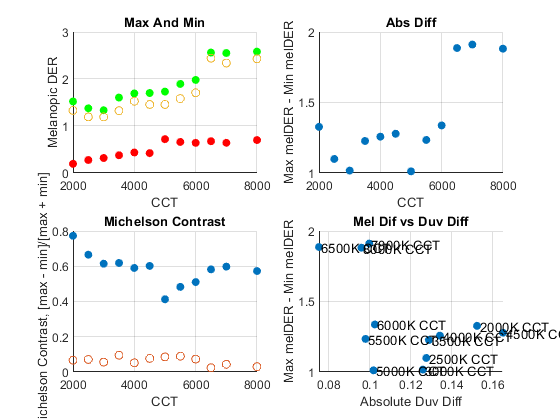

subplot(2,2,1)
% get(sp1)
scatter(minDataLMSRef.cctRef, minDataLMSRef.melDER)

subplot(2,2,3)

scatter(maxData(:,1), [maxData(:,2)-minDataLMSRef.melDER']./[maxData(:,2)+ minDataLMSRef.melDER'])

% clear all
% load('MinMelDER_CCTSweep_LMSRef_111521.mat')
Smin = SweepStructArray2d;
load('MaxMelDER_CCTSweep_DUV0.mat');
Smax = SweepStructArray2d;
[a,b] = max( (reshape( [SweepStructArray2d.melOpicDER], height(SweepStructArray2d),[])), [],1,'linear'); %max of each column
Smax = SweepStructArray2d(b);
AMax = [Smax.cct; Smax.melOpicDER; Smax.sOpicDER; Smax.lOpicDER; Smax.mOpicDER]

AMax =          2000         3000         4000         5000         6000         7000         8000
      0.66936       1.1508        1.408       1.6137       1.7777       1.9088       2.0146
     0.090064      0.27823      0.48611      0.66787      0.81903      0.94296       1.0445
       1.0466       1.0497       1.0502       1.0551       1.0609       1.0665       1.0714
      0.76304      0.94401       1.0325       1.0936       1.1382       1.1721       1.1984



% AMax = SweepStructArray2d(b);

AMin = [Smin.cct; Smin.melOpicDER; Smin.sOpicDER; Smin.lOpicDER; Smin.mOpicDER]

AMin =        2424.6       2424.6       2424.6       2424.6       2424.6       3371.2       3371.2       3371.2       3371.2       3371.2       4452.3       4452.3       4452.3       4452.3       4452.3
      0.38411      0.38411      0.38411      0.38411      0.38411       1.0198       1.0198       1.0198       1.0198       1.0198       1.2915       1.2915       1.2915       1.2915       1.2915
     0.090064     0.090064     0.090064     0.090064     0.090064      0.27823      0.27823      0.27823      0.27823      0.27823      0.48611      0.48611      0.48611      0.48611      0.48611
       1.0466       1.0466       1.0466       1.0466       1.0466       1.0497       1.0497       1.0497       1.0497       1.0497       1.0502       1.0502       1.0502       1.0502       1.0502
      0.76304      0.76304      0.76304      0.76304      0.76304      0.94401      0.94401      0.94401      0.94401      0.94401       1.0325       1.0325       1.0325       1.0325       1.0325


AMax - AMin

Arrays have incompatible sizes for this operation.

Related documentation